clear;
n=2;
coordinate=sym("u%d",[n,1]);
X=[ cos(coordinate(2))*(0.5*sin(coordinate(1))+1)
 sin(coordinate(2))*(0.5*sin(coordinate(1))+1)
0.5*cos(coordinate(1))];
uinterval=[0,2*pi];
vinterval=[0,2*pi];
hh=differential_geometry("n",n,"coordinate",coordinate,"X",X);

hh();
hh.connection

$$\left(\begin{array}{cc} 0 & 0\\ 0 & \frac{\cos\left(u_{1}\right)}{\sin\left(u_{1}\right)+2} \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & -\cos\left(u_{1}\right)\,\left(\sin\left(u_{1}\right)+2\right)\\ \frac{\cos\left(u_{1}\right)}{\sin\left(u_{1}\right)+2} & 0 \end{array}\right)$$

hh.g

$$ans = \left(\begin{array}{cc} \frac{1}{4} & 0\\ 0 & \frac{{\left(\sin\left(u_{1}\right)+2\right)}^{2}}{4} \end{array}\right)$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = \frac{8\,\sin\left(u_{1}\right)}{\sin\left(u_{1}\right)+2}$$

hh.Gauss_curvature

$$ans = \frac{4\,\sin\left(u_{1}\right)}{\sin\left(u_{1}\right)+2}$$

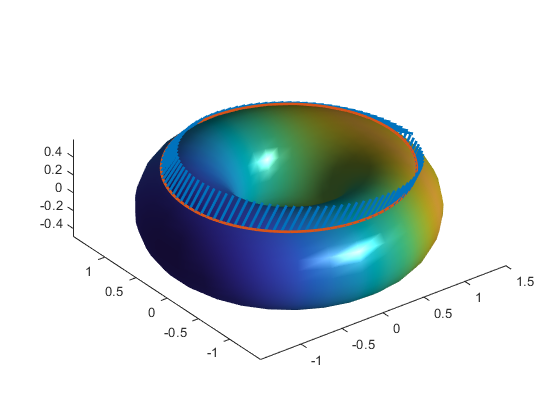

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.5;t];
% hh.scale=0;
hh.parallel_transport(u,[0;2*pi],[1,0],100);
axis image;

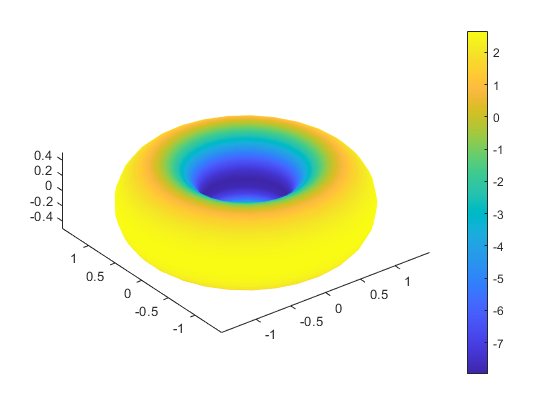

figure;
hh.drawmesh(uinterval,vinterval,1);
axis image;

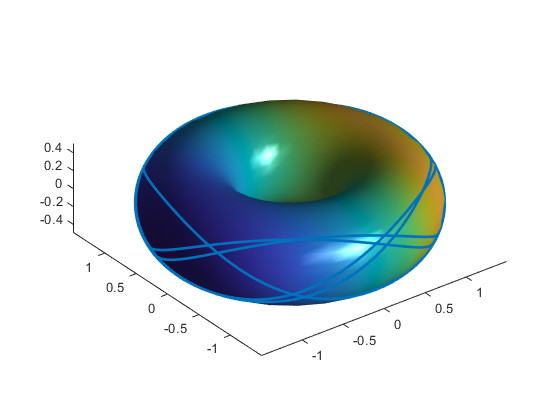

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,300],[0.1, 0.1, 1, 1],500);
axis image;